# Séance 2 : Comparaison de régulateur continu et discret 

Cette séance à pour but de comparer deux types de synthèse de régulateur discret. La première méthode étudiée consiste à synthétiser un régulateur continu pour ensuite le discrètiser et la seconde méthode consiste à discrètiser le système à réguler dans un premier temps pour ensuite synthétiser un régulateur sur base de ce système discret

Soit le système H(s)


$$\frac{7\text{ }\left(s+1\right)}{s\left(3s+1\right)}$$


H = tf([7 7],[3 1 0]);

## Synthèse d'un régulateur continu avant discrètisation

Dans cette section, c'est la première méthode qui est suivie. 

L'objectif est de créer un régulateur continu pour qu'en boucle fermée ce dernier respecte les conditions suivantes :

- pas de dépassement 

- un temps de réponse de 5 à 95% (3T)

Nous avons alors conçu un régulateur de compensation en simplifiant pôle et zéros tout en conservant l'intégrateur 

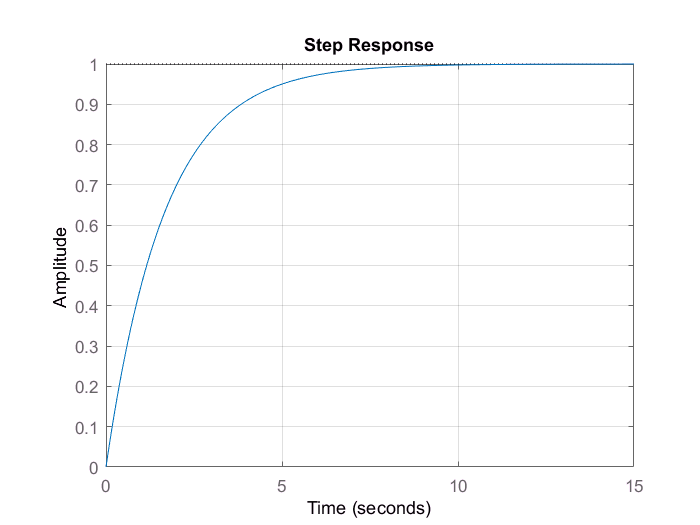

grid

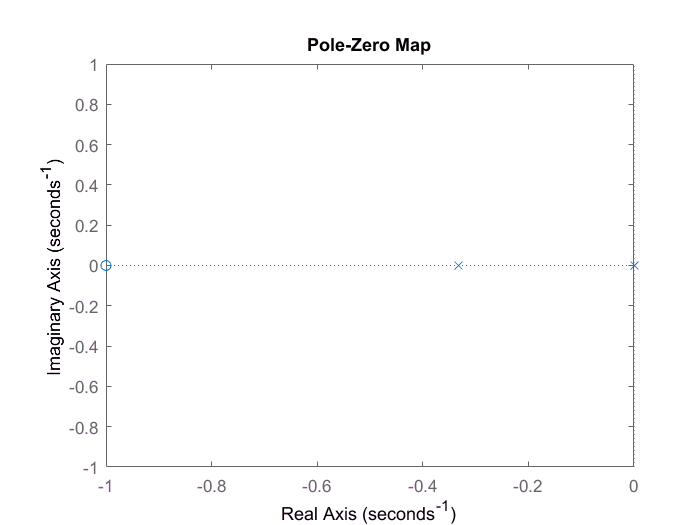

pzmap(H)

Le régulateur va simplifier le **pôle en 0.33 **ainsi que le zéro en -1. Le gain d'**Evans **sera alors de 2.33 avant correction

[Zc, Pc, kc] = zpkdata(H, 'v');

R = zpk(Pc(2), Zc, 1/kc);

En effet, le gain du régulateur doit être modifié pour respecter la condition dépassement (3T = 5), le gain alors corrigé est égal à 

K = (5/3)^(-1);

L'équation du régulateur continu peut alors être calculée ainsi que la réponse en boucle ouverte et en boucle fermée du système 

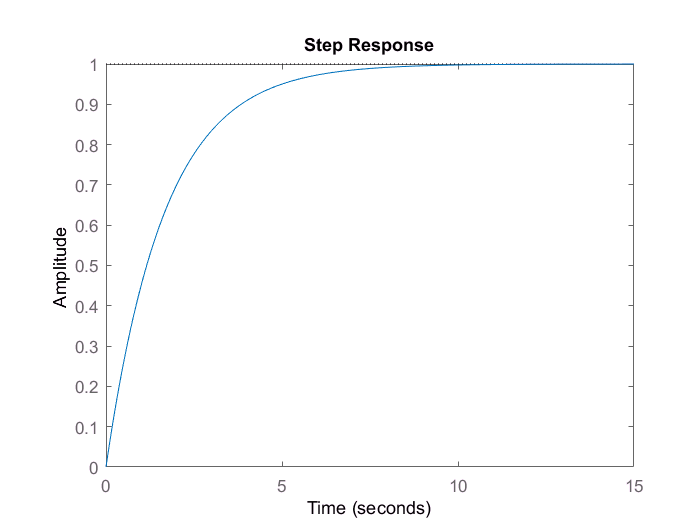

R = K*R;

Bo = R*H;

Bf = Bo /(1 + Bo);
Bf = minreal(Bf);

step(Bf)

Nous pouvons dès lors discrètiser ce régulateur par les **différences finies à gauche **avec 3 périodes d'échantillonnage différentes (h)

h = [0.01 0.5 2]
Rd = c2d(R, h(1)) % Pas si différent que les différence finie à gauche mais c'est pas la méthode demandée dans l'énoncée

## Synthèse d'un régulateur sur base d'un système discrètisé

Cette section étudie la deuxième méthode de synthèse de régulateur discret. Commé énoncé dans l'introduction, le régulateur discret de compensation est synthètiser sur base du système discrètisé. La transmittance discrète du système est alors obtenue par la méthode de l'équivalent échantilloné bloqué avec h = 1.

Hd = c2d(H,1); % Pas sur que ce soit la bonne commande pour l'équivalent échantilloné bloqué

Suivant la même démarche que lors de la synthèse du régulateur continu, nous pouvons déterminer l'équation du régulateur discret sur base de la transmittance discrète du système

[Zd, Pd, kd] = zpkdata(Hd, 'v');
Rd2 = zpk(Pc(2), Zc, 1/kc);
minreal(Rd2)

% Calcul de K pour avoir pdf = e^(sh) = e^((-3/5)*h)